
clear;
frequency = [4 8 12];
ks = 0;
E_oil = 3;
E_air = 1;
temp = 20;
salinity = 35;
theta = 0;
variance = 0.02;
tmin = 1;
tmax = 10;
thickness_step = 0.5;
thickness = tmin:thickness_step:tmax;
M = 5;

R_oil = reflectivity(frequency, thickness, ks, E_oil, E_air, temp, salinity, theta);

E_water_prob = abs(E_water(temp, salinity, frequency));
R_water = ((sqrt(E_air) - sqrt(E_water_prob))/(sqrt(E_air) + sqrt(E_water_prob)))^2;
noise = sqrt(variance) * randn(length(frequency), length(R_oil));    
noisy_water = R_water + noise;




samples = 1000;
prob = double.empty;

tic
for i = tmin:thickness_step:tmax
    desired_reflectivity  = reflectivity(frequency, i, ks, E_oil, E_air, temp, salinity, theta);
    oil = 0;
    for j = 1:samples       
        oil_found = Detect_with_unknown_thickness(desired_reflectivity, M, frequency, ks, variance, E_oil, E_air, temp, salinity, theta, tmin, thickness_step, tmax);
       
        if oil_found == 1
            oil = oil + 1;
        end
    end
    
    prob(length(prob) + 1) = oil/samples;
    
end
toc

Elapsed time is 1.353815 seconds.


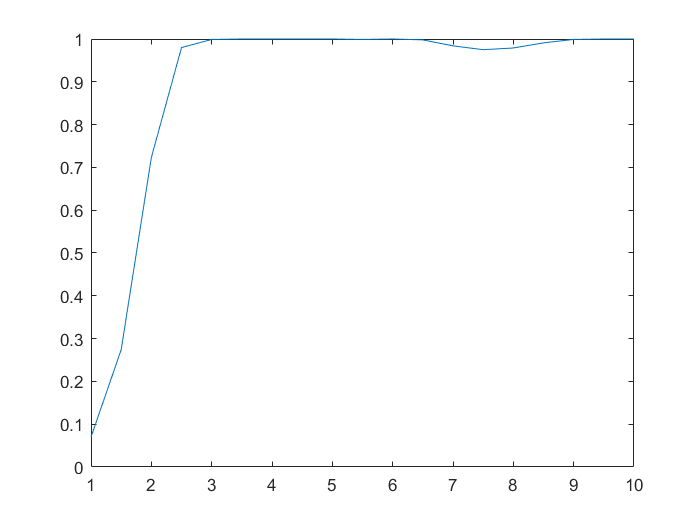

plot(thickness, prob);